# Lab 3 by Cole Bardin		Section 61

## Model of a Spring-Mass-Damper

## Part A

clc, clear, close all

% Question 1    Constants for the spring-mass-damper system.
% First look at the homogeneous case where the forcing term is zero.
% That is, f(t) = 0.
% Constants entered for you as symbols.
m = sym(9); b = sym(12); k = sym(229);

% Find the roots of the characteristic equation:
char_poly = [m, b, k] % <- Fix this stub. 

$$char\_poly = \left(\begin{array}{ccc} 9 & 12 & 229 \end{array}\right)$$


roots = roots(char_poly) % find roots of char poly

$$roots = \left(\begin{array}{c} -\frac{2}{3}-5\,\mathrm{i}\\ -\frac{2}{3}+5\,\mathrm{i} \end{array}\right)$$


% Question 2
D = b^2 -4*m*k

$$D = -8100$$


% Question 3
clear
syms y(t)
Dy = diff(y,t); D2y = diff(y,t,t);
m = 9; b = 12; k = 229;
DE = m*D2y + b * Dy + k * y == 0;

sol = dsolve(DE, y(0)==3, Dy(0)==-2);

% Question 4
% Exact solution and its derivative.
y = matlabFunction(sol)

y = function_handle with value:
    @(t)cos(t.*5.0).*exp(t.*(-2.0./3.0)).*3.0


Dy = matlabFunction(diff(y,t))

Dy = function_handle with value:
    @(t)cos(t.*5.0).*exp(t.*(-2.0./3.0)).*-2.0-sin(t.*5.0).*exp(t.*(-2.0./3.0)).*1.5e+1


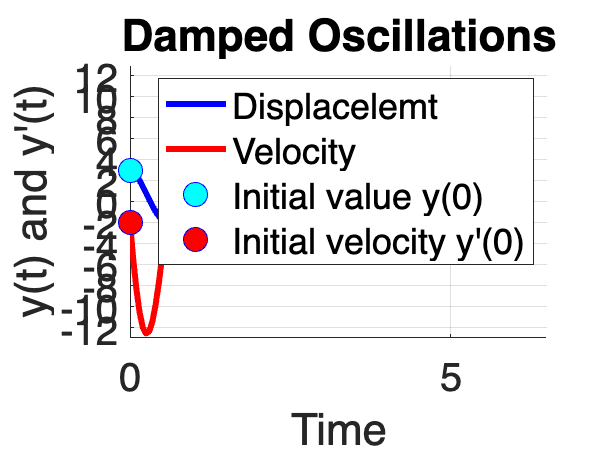


% Question 5
x = 0:0.05:2*pi;
hold on
grid on
yt = plot(x, y(x), 'b', "LineWidth", 3);
ypt = plot(x, Dy(x), 'r', "LineWidth", 3);
y0 = plot(0, 3, 'bo', "MarkerSize", 12, "MarkerFaceColor", 'c');
yp0 = plot(0, -2, 'bo', "MarkerSize", 12, "MarkerFaceColor", 'r');

set(gca, 'FontSize', 20)
title("Damped Oscillations")
xlabel("Time")
ylabel("y(t) and y'(t)")
axis([0, 6.5, -13, 13])
yticks(-12:2:12)
legend([yt, ypt, y0, yp0], ["Displacelemt", "Velocity", "Initial value y(0)", "Initial velocity y'(0)"])

## Part B

clc, clear, close all

% Question 6
x0=[3;-2];
smd(0,x0)

ans =    -2.0000
  -73.6667


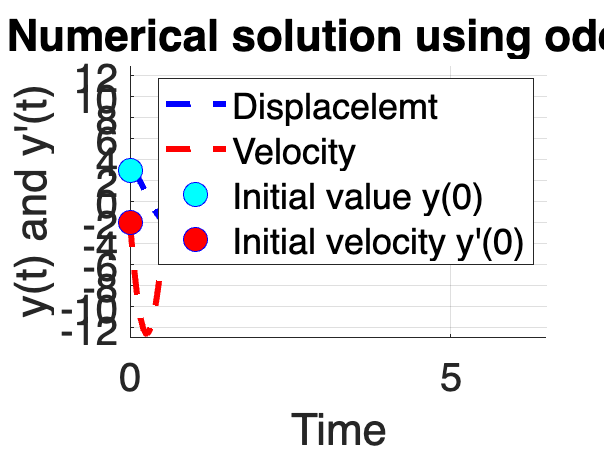


% Question 7
tf = 2*pi; % Final time.
[t,x] = ode45(@smd, [0,tf], x0);
hold on
grid on
yt = plot(t,x(:,1), 'b--', "LineWidth",3);
ypt = plot(t,x(:,2), 'r--', "LineWidth",3);
y0 = plot(0, 3, 'bo', "MarkerSize", 12, "MarkerFaceColor", 'c');
yp0 = plot(0, -2, 'bo', "MarkerSize", 12, "MarkerFaceColor", 'r');
set(gca, 'FontSize', 20)
title("Numerical solution using ode45")
xlabel("Time")
ylabel("y(t) and y'(t)")
axis([0, 6.5, -13, 13])
yticks(-12:2:12)
legend([yt, ypt, y0, yp0], ["Displacelemt", "Velocity", "Initial value y(0)", "Initial velocity y'(0)"])

## Questions 8-10

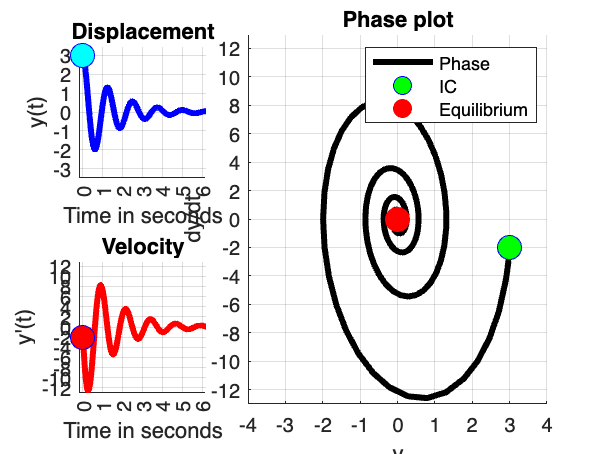

clc, clear, close all

x0=[3;-2];
tf = 2*pi; % Final time.
[t,x] = ode45(@smd, [0,tf], x0);

set(gca, "FontSize", 20)
subplot(2,3,1)
hold on
grid on
yt = plot(t,x(:,1), 'b', "LineWidth",3);
y0 = plot(0, 3, 'bo', "MarkerSize", 12, "MarkerFaceColor", 'c');
axis([-0.2,6.2, -3.5,3.5])
yticks(-3:3)
xticks(0:6)
title("Displacement")
ylabel("y(t)")
xlabel("Time in seconds")

subplot(2,3,4)
hold on
grid on
ypt = plot(t,x(:,2), 'r', "LineWidth",3);
yp0 = plot(0, -2, 'bo', "MarkerSize", 12, "MarkerFaceColor", 'r');
axis([-0.2,6.2, -13,13])
yticks(-12:2:12)
xticks(0:6)
title("Velocity")
ylabel("y'(t)")
xlabel("Time in seconds")

subplot(2,3,[2,3,5,6])
grid on
hold on
phase = plot(x(:,1), x(:,2), 'k', "LineWidth",3);
ic = plot(x0(1), x0(2), 'bo', "MarkerSize",12, "MarkerFaceColor",'g');
eq = plot(0,0, 'ro', "MarkerSize",12, "MarkerFaceColor",'r');
axis([-4,4, -13,13])
yticks(-12:2:12)
xticks(-4:4)
title("Phase plot")
ylabel("dy/dt")
xlabel("y")
legend([phase, ic, eq], ["Phase", "IC", "Equilibrium"])